Entrenamiento Modelo ART.

clc
clear all

E1 = [1 1 0 0]

E1 =      1     1     0     0


E2 = [0 0 1 1]

E2 =      0     0     1     1


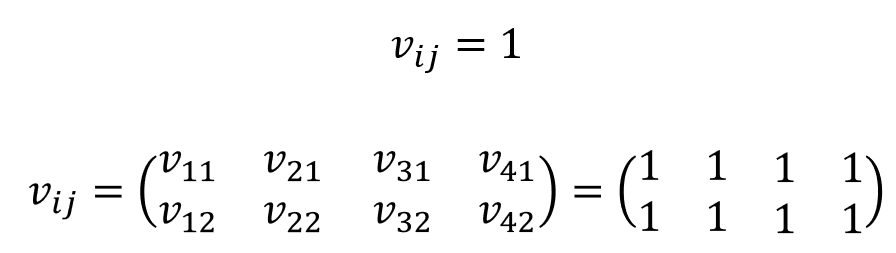

V = ones(2,length(E1))

V =      1     1     1     1
     1     1     1     1


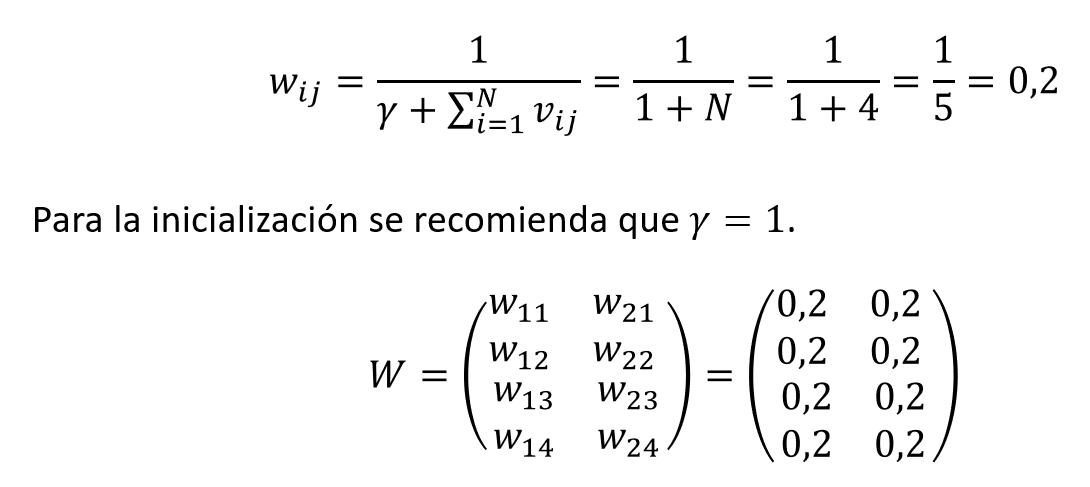

lamda = 1;
w_ini = 1 / (lamda + length(E1));
W = ones(length(E1),2)*w_ini

W =     0.2000    0.2000
    0.2000    0.2000
    0.2000    0.2000
    0.2000    0.2000


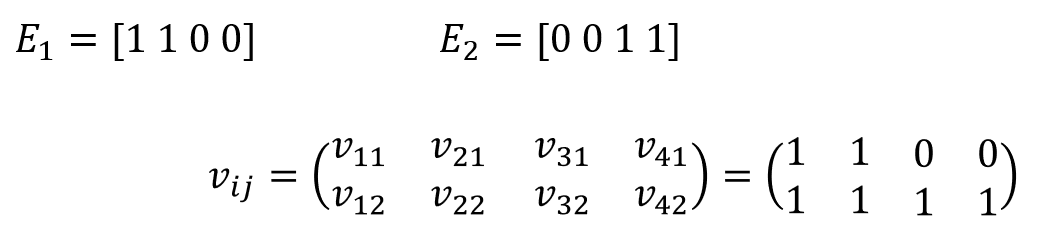

V(1,:) = E1

V =      1     1     0     0
     1     1     1     1


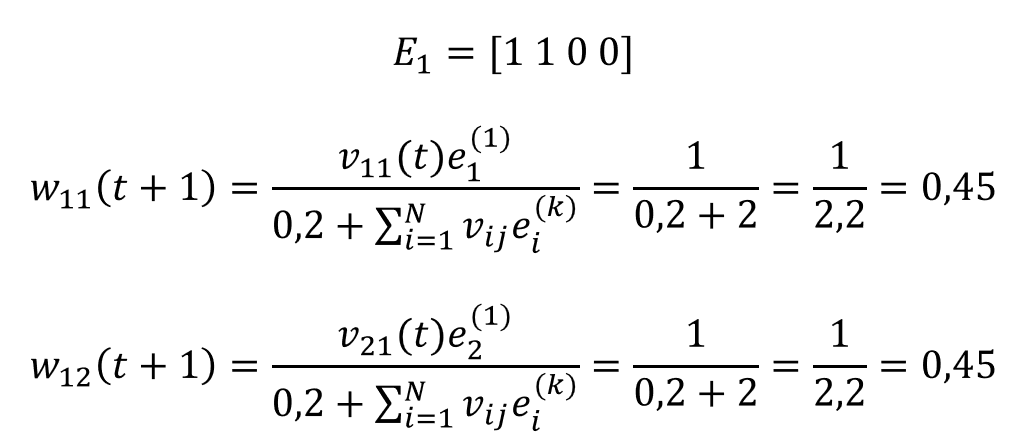

lamda = 0.2;

W(1,1) = E1(1) / (lamda + sum(E1));
W(2,1) = E1(2) / (lamda + sum(E1));
W(3,1) = E1(3) / (lamda + sum(E1));
W(4,1) = E1(4) / (lamda + sum(E1))

W =     0.4545    0.2000
    0.4545    0.2000
         0    0.2000
         0    0.2000


Se realiza nuevamente el mismo procesmiento para el patron E2

V(2,:) = E2

V =      1     1     0     0
     0     0     1     1


W(1,2) = E2(1) / (lamda + sum(E2));
W(2,2) = E2(2) / (lamda + sum(E2));
W(3,2) = E2(3) / (lamda + sum(E2));
W(4,2) = E2(4) / (lamda + sum(E2))

W =     0.4545         0
    0.4545         0
         0    0.4545
         0    0.4545


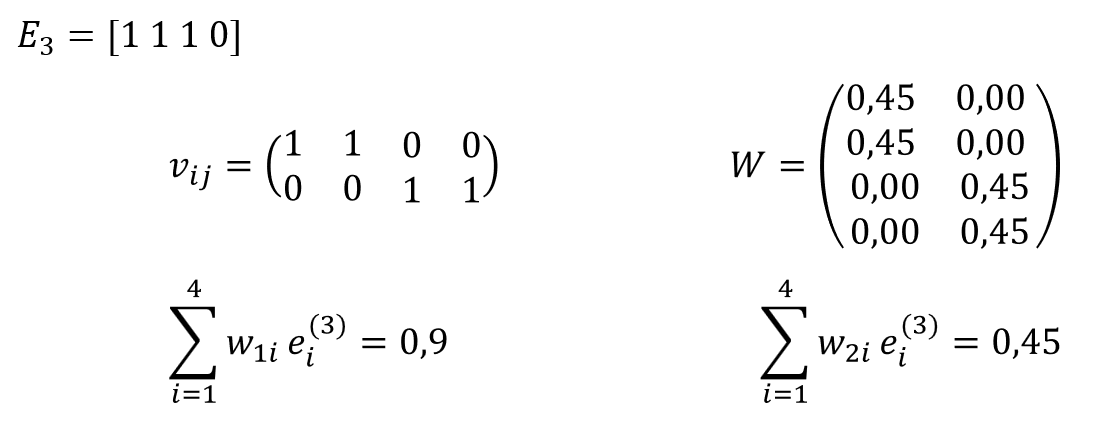

E3 = [1 1 1 0]

E3 =      1     1     1     0



Y = E3 * W

Y =     0.9091    0.4545


[valor, indice] = max(Y)

valor = 0.9091

indice = 1

Salida_RN = V(indice,:)

Salida_RN =      1     1     0     0



parametro_vigilancia = 0.8

parametro_vigilancia = 0.8000

Relacion_semejanza = sum(E3 .* Salida_RN)/sum(E3)  

Relacion_semejanza = 0.6667


if (Relacion_semejanza < parametro_vigilancia)
    V(3,:) = E3
    W(1,3) = E3(1) / (lamda + sum(E3));
    W(2,3) = E3(2) / (lamda + sum(E3));
    W(3,3) = E3(3) / (lamda + sum(E3));
    W(4,3) = E3(4) / (lamda + sum(E3))    
end

V =      1     1     0     0
     0     0     1     1
     1     1     1     0


W =     0.4545         0    0.3125
    0.4545         0    0.3125
         0    0.4545    0.3125
         0    0.4545         0
